## Construct 3-phase sampled signal

You could either create a synthetic signal or read a sampled signal from a file:

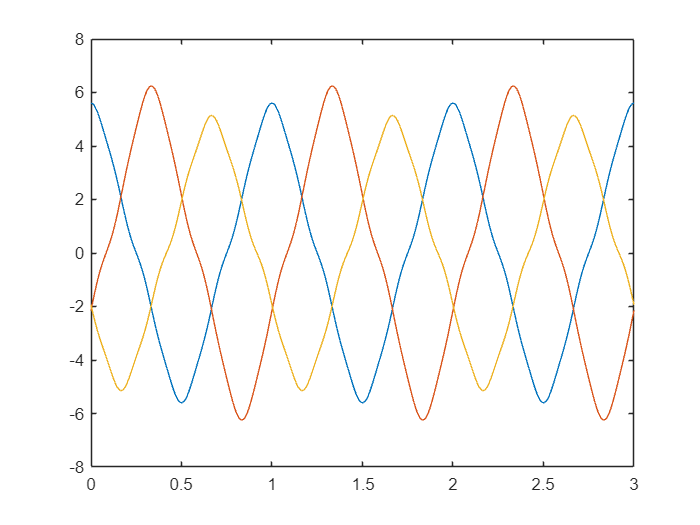

% Fundamental frequency
f = 1;
w = 2 * pi * f;

% Sampling rate in samples/cycle
fs = 1000;

% Signal cycles count
nc = 3;

% Sampled time
t = linspace(0, nc / f, fs * nc + 1);

% Signal sample count
n = length(t);

% Harmonic Signal components
angles = [w * t; w * t - 2 * pi / 3; w * t + 2 * pi / 3];

m = [
    5, 0.5, 0.1; 
    5.5, 0.65, 0.09; 
    4.6, 0.42, 0.12
];

a = m(1,1) * cos(angles(1,:)) + m(1,2) * cos(3 * angles(1,:)) + m(1,3) * cos(7 * angles(1,:));
b = m(2,1) * cos(angles(2,:)) + m(2,2) * cos(3 * angles(2,:)) + m(2,3) * cos(7 * angles(2,:));
c = m(3,1) * cos(angles(3,:)) + m(3,2) * cos(3 * angles(3,:)) + m(3,3) * cos(7 * angles(3,:));

signal = [a; b; c];

plot(t,a);
hold on;
plot(t,b);
plot(t,c);
hold off;

## Curve projection to 2D plane

% We can use PCA for selecting 2 basis vectors for plane of projection
% Make sure signal is nearly centered at the origin
dataCenter = mean(signal, 2)

dataCenter =     0.0019
   -0.0007
   -0.0006


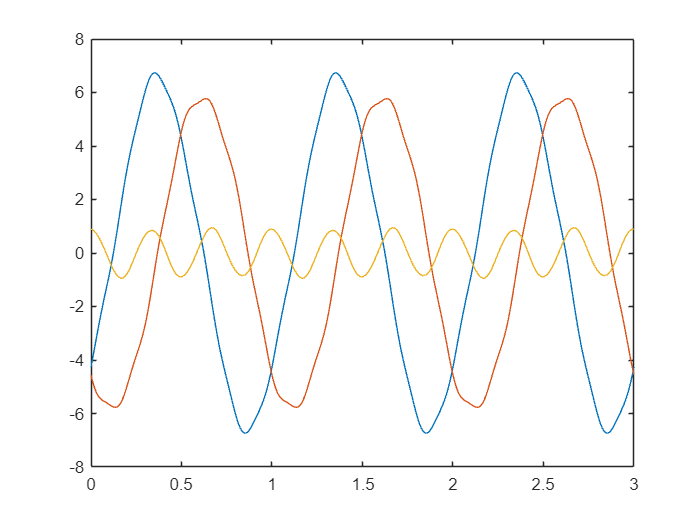

%[pc,score,latent] = pca(signal')
pc = pca(signal');

% The first two PC vectors define the plane that best fits the signal
pc1 = repmat(pc(:,1), [1, n]);
pc2 = repmat(pc(:,2), [1, n]);

% acos(sum(pc1 .* signal,1) ./ sqrt(sum(signal .* signal, 1))) * 180 / pi
% acos(sum(pc2 .* signal,1) ./ sqrt(sum(signal .* signal, 1))) * 180 / pi

% The 3rd PC vector is mostly normal to all signal samples
pcNormal = repmat(pc(:,3), [1, n]);
% acos(sum(pcNormal .* signal,1) ./ sqrt(sum(signal .* signal, 1))) * 180 / pi

% We can use SKR to rotate signal by aligning 3rd PC vector with z-axis
% Or we could directly project each singal sample on the best-fit plane's basis
% The two methods give same results, but PCA method is simpler

% vectors (i.e. the first 2 PC vectors)
p1 = sum(pc1 .* signal, 1);
p2 = sum(pc2 .* signal, 1);
pNormal = sum(pcNormal .* signal, 1);
plot(t,p1); hold on; plot(t,p2); plot(t,pNormal); hold off;

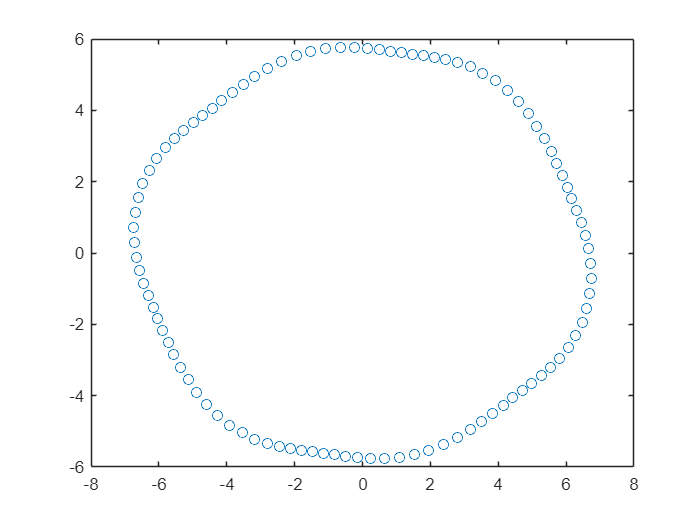

% Now we can take first 2 projected signal components and try finding the best-fit ellipse
points = [p1; p2];

% We probably should down-sample the signal here, we don't practically need all
% these samples
points = points(:, 1:10:n);
n = size(points, 2);

% Plot points
plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");

## Global Optimization Algorithm

[centerX, centerY, majorTheta, majorLength, minorLength] = fitEllipseGAC(points)

centerX = -4.5074e-04

centerY = -5.9378e-04

majorTheta = 0.0037

majorLength = 6.6232

minorLength = 5.7532

## Draw final results

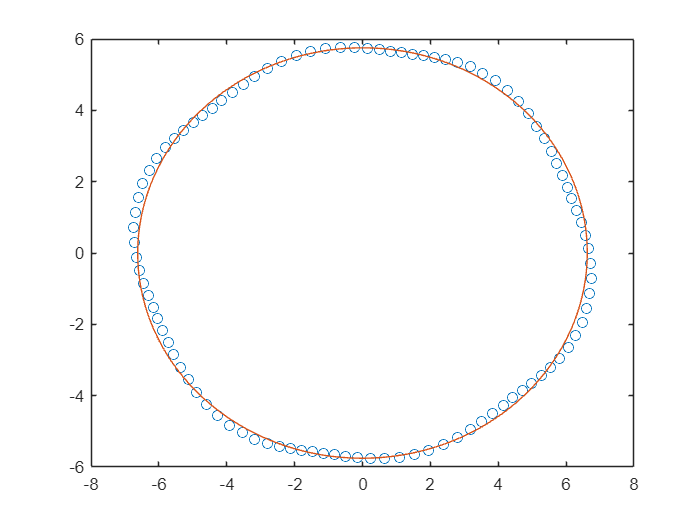

% Ellipse points
ellipsePoints = getEllipsePoints(majorLength, minorLength, majorTheta, centerX, centerY, 361);

% Plot points
plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");
hold on;
plot(ellipsePoints(1,:), ellipsePoints(2,:), "LineStyle","-");
hold off;